% Initialization
close all
clear all
clc

% Symbolic variables
syms x y t real
syms pi
I=sym(eye(2));

% Parameters
% syms gamma x0 y0 beta real
% assume(gamma>1)
% assume(beta>1)
gamma=7/5; x0=5; y0=0; beta=5;

% Spatial coordinates
X=[x,y];

% Given data
R=sqrt((x-x0-t)^2+(y-y0)^2);
r=(1-(gamma-1)/(16*gamma*pi^2)*beta^2*exp(2*(1-R^2)))^(1/(gamma-1))

$$r = {\left(1-\frac{25\,{\mathrm{e}}^{2-2\,y^{2}-2\,{\left(t-x+5\right)}^{2}}}{56\,\pi^{2}}\right)}^{5/2}$$

assume(r>0)
v=[1-beta*exp(1-R^2)*(y-y0)/(2*pi)
     beta*exp(1-R^2)*(x-x0)/(2*pi)]

$$v = \left[\begin{array}{c} 1-\frac{5\,y\,{\mathrm{e}}^{1-y^{2}-{\left(t-x+5\right)}^{2}}}{2\,\pi }\\ \frac{5\,{\mathrm{e}}^{1-y^{2}-{\left(t-x+5\right)}^{2}}\,\left(x-5\right)}{2\,\pi } \end{array}\right]$$

p=r^gamma

$$p = {\left({\left(1-\frac{25\,{\mathrm{e}}^{2-2\,y^{2}-2\,{\left(t-x+5\right)}^{2}}}{56\,\pi^{2}}\right)}^{5/2}\right)}^{7/5}$$


% Analytical solution
r=r

$$r = {\left(1-\frac{25\,{\mathrm{e}}^{2-2\,y^{2}-2\,{\left(t-x+5\right)}^{2}}}{56\,\pi^{2}}\right)}^{5/2}$$

w=r*v

$$w = \left[\begin{array}{c} -\left(\frac{5\,y\,{\mathrm{e}}^{1-y^{2}-{\left(t-x+5\right)}^{2}}}{2\,\pi }-1\right)\,{\left(1-\frac{25\,{\mathrm{e}}^{2-2\,y^{2}-2\,{\left(t-x+5\right)}^{2}}}{56\,\pi^{2}}\right)}^{5/2}\\ \frac{5\,{\mathrm{e}}^{1-y^{2}-{\left(t-x+5\right)}^{2}}\,{\left(1-\frac{25\,{\mathrm{e}}^{2-2\,y^{2}-2\,{\left(t-x+5\right)}^{2}}}{56\,\pi^{2}}\right)}^{5/2}\,\left(x-5\right)}{2\,\pi } \end{array}\right]$$

g=p/(gamma-1)+1/2*r*(v(1)^2+v(2)^2)

$$g = \frac{\left({\left(\frac{5\,y\,{\mathrm{e}}^{1-y^{2}-{\left(t-x+5\right)}^{2}}}{2\,\pi }-1\right)}^{2}+\frac{25\,{\mathrm{e}}^{2-2\,y^{2}-2\,{\left(t-x+5\right)}^{2}}\,{\left(x-5\right)}^{2}}{4\,\pi^{2}}\right)\,{\left(1-\frac{25\,{\mathrm{e}}^{2-2\,y^{2}-2\,{\left(t-x+5\right)}^{2}}}{56\,\pi^{2}}\right)}^{5/2}}{2}+\frac{5\,{\left({\left(1-\frac{25\,{\mathrm{e}}^{2-2\,y^{2}-2\,{\left(t-x+5\right)}^{2}}}{56\,\pi^{2}}\right)}^{5/2}\right)}^{7/5}}{2}$$


% Rhs terms
f_r=(beta^3*t*exp(3-3*(t-x+x0)^2-3*(y-y0)^2)*(y-y0)*(1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1)-1))/(8*gamma*pi^3)-(beta*t*exp(1-(t-x+x0)^2-(y-y0)^2)*(y-y0)*(1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1)))/pi;
f_w=[(beta*exp(1-(t-x+x0)^2-(y-y0)^2)*(y-y0)*(1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1))*(2*t-2*x+2*x0))/(2*pi)-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(x-x0)*(1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1))*(-2*y^2+4*y*y0-2*y0^2+1))/(4*pi^2)-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*((1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1)))^(gamma-1)*(4*t-4*x+4*x0))/(16*pi^2*(-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2)+1)^((gamma-2)/(gamma-1)))-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*((beta*exp(1-(t-x+x0)^2-(y-y0)^2)*(y-y0))/(2*pi)-1)^2*(4*t-4*x+4*x0))/(16*gamma*pi^2*(-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2)+1)^((gamma-2)/(gamma-1)))+(beta*exp(1-(t-x+x0)^2-(y-y0)^2)*((beta*exp(1-(t-x+x0)^2-(y-y0)^2)*(y-y0))/(2*pi)-1)*(y-y0)*(1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1))*(2*t-2*x+2*x0))/pi+(beta*exp(1-(t-x+x0)^2-(y-y0)^2)*(2*y-2*y0)*((beta*exp(1-(t-x+x0)^2-(y-y0)^2)*(y-y0))/(2*pi)-1)*(x-x0)*(1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1)))/(2*pi)-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*((beta*exp(1-(t-x+x0)^2-(y-y0)^2)*(y-y0))/(2*pi)-1)*(4*t-4*x+4*x0))/(16*gamma*pi^2*(-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2)+1)^((gamma-2)/(gamma-1)))-(beta^3*exp(3-3*(t-x+x0)^2-3*(y-y0)^2)*(4*y-4*y0)*((beta*exp(1-(t-x+x0)^2-(y-y0)^2)*(y-y0))/(2*pi)-1)*(x-x0))/(32*gamma*pi^3*(-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2)+1)^((gamma-2)/(gamma-1)))
     (beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(4*y-4*y0)*((1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1)))^(gamma-1)*(1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1)-1))/(16*pi^2)-(beta*exp(1-(t-x+x0)^2-(y-y0)^2)*((beta*exp(1-(t-x+x0)^2-(y-y0)^2)*(y-y0))/(2*pi)-1)*(1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1)))/(2*pi)-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(4*y-4*y0)*(x-x0)^2*(1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1)))/(4*pi^2)-(beta*exp(1-(t-x+x0)^2-(y-y0)^2)*(x-x0)*(1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1))*(2*t-2*x+2*x0))/(2*pi)-(beta*exp(1-(t-x+x0)^2-(y-y0)^2)*((beta*exp(1-(t-x+x0)^2-(y-y0)^2)*(y-y0))/(2*pi)-1)*(x-x0)*(1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1))*(2*t-2*x+2*x0))/(2*pi)-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(x-x0)*(y-y0)*(1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1))*(2*t-2*x+2*x0))/(4*pi^2)+(beta^4*exp(4-4*(t-x+x0)^2-4*(y-y0)^2)*(4*y-4*y0)*(x-x0)^2*(1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1)-1))/(64*gamma*pi^4)+(beta^3*exp(3-3*(t-x+x0)^2-3*(y-y0)^2)*(x-x0)*(1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1)-1)*(4*t-4*x+4*x0))/(32*gamma*pi^3)+(beta^3*exp(3-3*(t-x+x0)^2-3*(y-y0)^2)*((beta*exp(1-(t-x+x0)^2-(y-y0)^2)*(y-y0))/(2*pi)-1)*(x-x0)*(1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1)-1)*(4*t-4*x+4*x0))/(32*gamma*pi^3)];
f_g=((beta*exp(1-(t-x+x0)^2-(y-y0)^2)*(y-y0))/(2*pi)-1)*((beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*((1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1)))^(gamma-1)*(4*t-4*x+4*x0))/(16*pi^2*(-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2)+1)^((gamma-2)/(gamma-1)))-((1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1))*((beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(2*x-2*x0))/(4*pi^2)+(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(x-x0)^2*(4*t-4*x+4*x0))/(4*pi^2)+(beta*exp(1-(t-x+x0)^2-(y-y0)^2)*((beta*exp(1-(t-x+x0)^2-(y-y0)^2)*(y-y0))/(2*pi)-1)*(y-y0)*(2*t-2*x+2*x0))/pi))/2+(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(((beta*exp(1-(t-x+x0)^2-(y-y0)^2)*(y-y0))/(2*pi)-1)^2+(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(x-x0)^2)/(4*pi^2))*(4*t-4*x+4*x0))/(32*gamma*pi^2*(-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2)+1)^((gamma-2)/(gamma-1)))+(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*((1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1)))^(gamma-1)*(4*t-4*x+4*x0))/(16*pi^2*(gamma-1)*(-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2)+1)^((gamma-2)/(gamma-1))))-((1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1))*((beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(x-x0)^2*(4*t-4*x+4*x0))/(4*pi^2)+(beta*exp(1-(t-x+x0)^2-(y-y0)^2)*((beta*exp(1-(t-x+x0)^2-(y-y0)^2)*(y-y0))/(2*pi)-1)*(y-y0)*(2*t-2*x+2*x0))/pi))/2+(beta*exp(1-(t-x+x0)^2-(y-y0)^2)*(x-x0)*((beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(4*y-4*y0)*((1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1)))^(gamma-1))/(16*pi^2*(-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2)+1)^((gamma-2)/(gamma-1)))-(((beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(4*y-4*y0)*(x-x0)^2)/(4*pi^2)-(beta*exp(1-(t-x+x0)^2-(y-y0)^2)*((beta*exp(1-(t-x+x0)^2-(y-y0)^2)*(y-y0))/(2*pi)-1)*(-2*y^2+4*y*y0-2*y0^2+1))/pi)*(1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1)))/2+(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(4*y-4*y0)*((1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1)))^(gamma-1))/(16*pi^2*(gamma-1)*(-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2)+1)^((gamma-2)/(gamma-1)))+(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(4*y-4*y0)*(((beta*exp(1-(t-x+x0)^2-(y-y0)^2)*(y-y0))/(2*pi)-1)^2+(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(x-x0)^2)/(4*pi^2)))/(32*gamma*pi^2*(-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2)+1)^((gamma-2)/(gamma-1)))))/(2*pi)-(beta*exp(1-(t-x+x0)^2-(y-y0)^2)*(y-y0)*(((((beta*exp(1-(t-x+x0)^2-(y-y0)^2)*(y-y0))/(2*pi)-1)^2+(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(x-x0)^2)/(4*pi^2))*(1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1)))/2+((1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1)))^gamma+((1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1)))^gamma/(gamma-1))*(2*t-2*x+2*x0))/(2*pi)-(beta*exp(1-(t-x+x0)^2-(y-y0)^2)*(2*y-2*y0)*(x-x0)*(((((beta*exp(1-(t-x+x0)^2-(y-y0)^2)*(y-y0))/(2*pi)-1)^2+(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(x-x0)^2)/(4*pi^2))*(1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1)))/2+((1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1)))^gamma+((1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1)))^gamma/(gamma-1)))/(2*pi)+(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(((beta*exp(1-(t-x+x0)^2-(y-y0)^2)*(y-y0))/(2*pi)-1)^2+(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(x-x0)^2)/(4*pi^2))*(4*t-4*x+4*x0))/(32*gamma*pi^2*(-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2)+1)^((gamma-2)/(gamma-1)))+(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*((1-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2))^(1/(gamma-1)))^(gamma-1)*(4*t-4*x+4*x0))/(16*pi^2*(gamma-1)*(-(beta^2*exp(2-2*(t-x+x0)^2-2*(y-y0)^2)*(gamma-1))/(16*gamma*pi^2)+1)^((gamma-2)/(gamma-1)));

% Check residual of density
R_r=simplify(...
    diff(r,t)...
    +mydivergence(r*v,X)...
    -f_r,...
    'Steps',100)

$$R\_r = 0$$


% Check residual of momentum
R_w=simplify(...
    diff(w,t)...
    +mydivergence(r*(v*transpose(v))+p*I,X)...
    -f_w,...
    'Steps',100)

$$R\_w = \left[\begin{array}{c} 0\\ 0 \end{array}\right]$$


% Check residual of energy
R_g=simplify(...
    diff(g,t)...
    +mydivergence((g+p)*v,X)...
    -f_g,...
    'Steps',100)

$$R\_g = 0$$

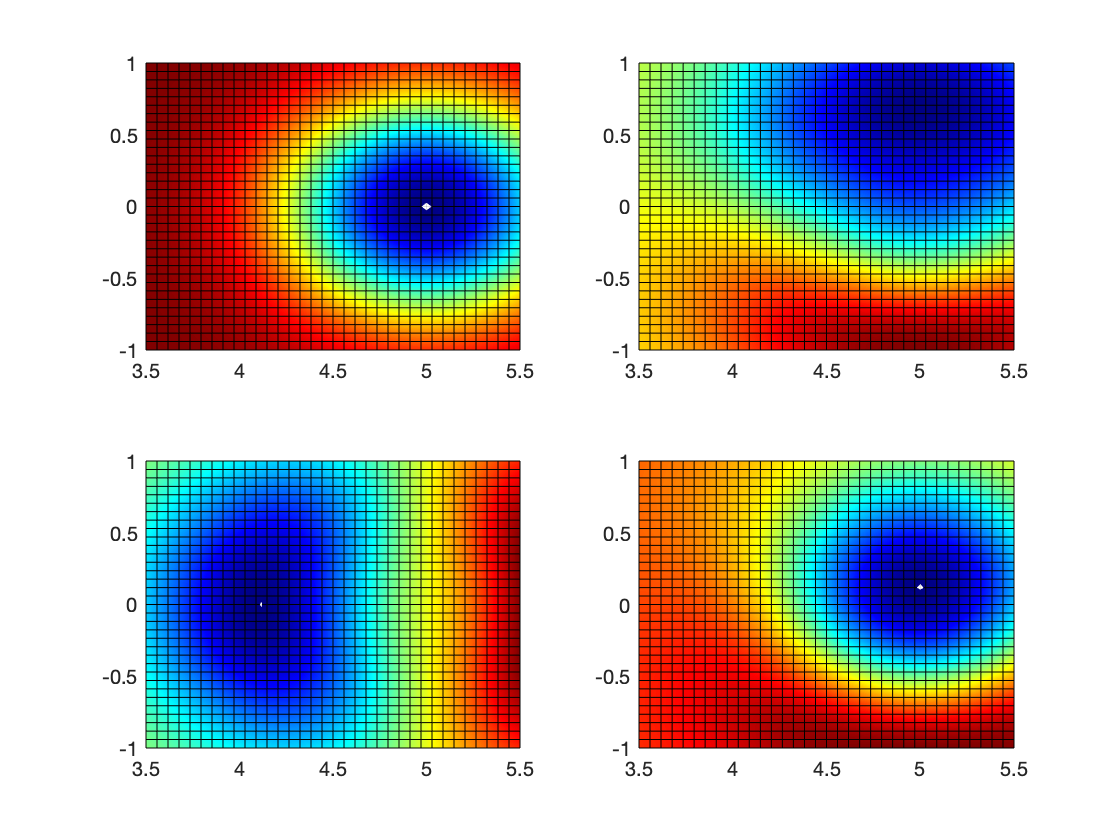


% Plot solution at t=1e-4
figure
subplot(2,2,1); fsurf(subs(r   ,t,1e-4),[3.5,5.5,-1,+1]); view(2); colormap('jet');
subplot(2,2,2); fsurf(subs(w(1),t,1e-4),[3.5,5.5,-1,+1]); view(2); colormap('jet');
subplot(2,2,3); fsurf(subs(w(2),t,1e-4),[3.5,5.5,-1,+1]); view(2); colormap('jet');
subplot(2,2,4); fsurf(subs(g   ,t,1e-4),[3.5,5.5,-1,+1]); view(2); colormap('jet');